# Customizable Assignment Report: Calculate Assignment Scores for each Learner from MATLAB Grader Assignment Report

Copyright 2021 The MathWorks, Inc

This script shows how to create a customizable assignment report, that is a list of students with the number of problems they saved correctly, the mean percentage score they received for problems or the number of points they scored for the assignment, from the assignment report generated in MATLAB Grader. It refers to the hosted version of MATLAB Grader at [grader.mathworks.com](https://grader.mathworks.com/).

## Get the Assignment Report 

You can generate an assignment report for each assignment in a MATLAB Grader course at [grader.mathworks.com](https://grader.mathworks.com/).

- Navigate to the assignment for which you would like to generate a report. Reports can only be generated from the assignment level.

- In the right hand corner click "Actions" and choose "Report".

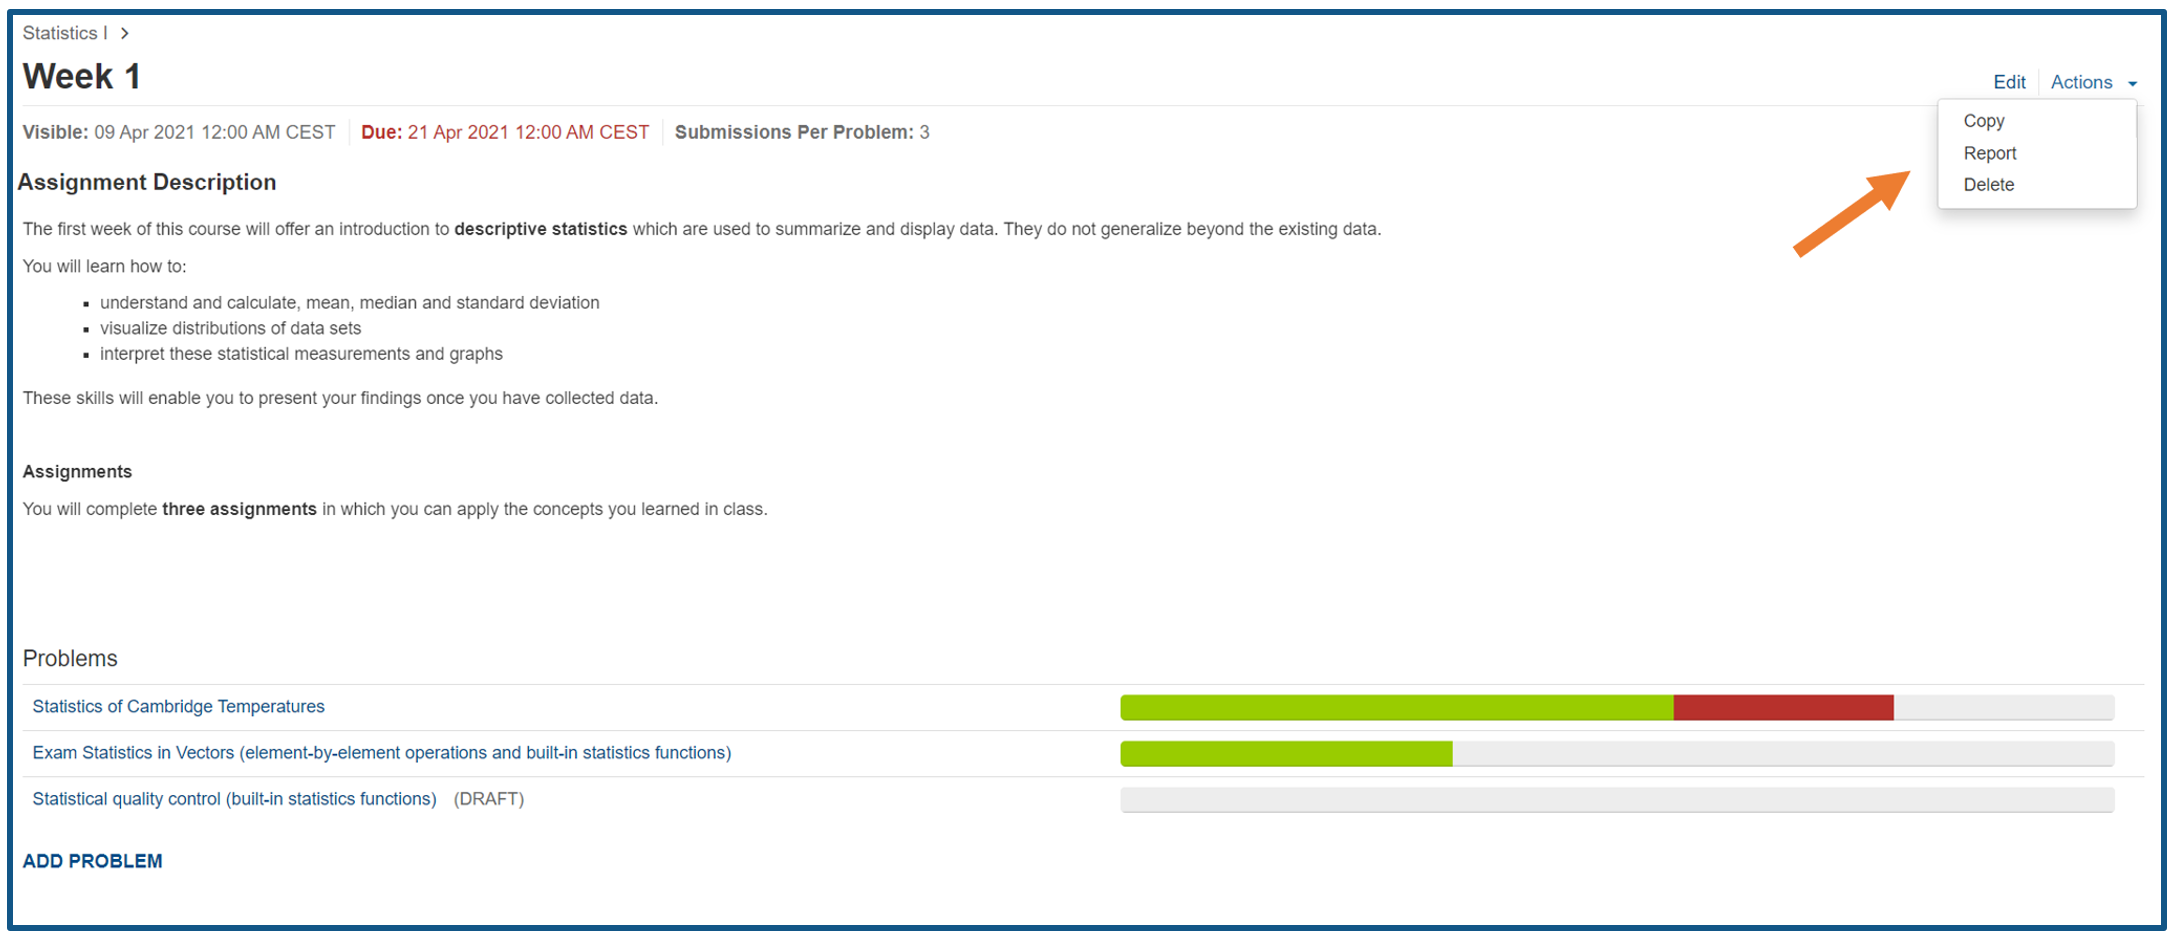

- Choose either "Best solutions as of due date" to only see the solutions submitted by the due date or "Best solution as of today" to also include late submissions. Choose "Excel" as output format.

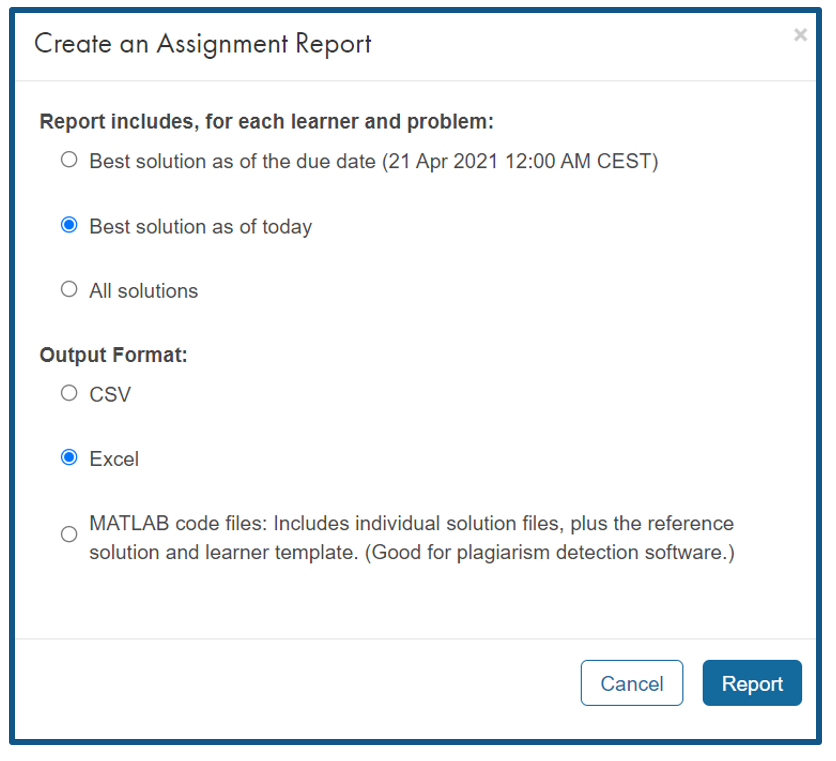

## Load report into MATLAB and display columns of interest

report_raw = readtable(fullfile(pwd,'example_week.xlsx'));

You will receive a warning that says "Column headers from the file were modified to make them valid MATLAB identifiers." This means column headers like "Student Name" were changed to "StudentName". 

Get all column headers:

columnHeaders = report_raw.Properties.VariableNames

columnHeaders = 1×17 cell array
    {'StudentName'}    {'StudentEmail'}    {'SolutionID'}    {'SubmissionComponentID'}    {'Solution'}    {'TestsPassed'}    {'TotalTests'}    {'SubmittedTime'}    {'Correct'}    {'Size'}    {'x_Score'}    {'ProblemID'}    {'ProblemTitle'}    {'ProblemComponentID'}    {'AssignmentID'}    {'AssignmentTitle'}    {'LateSubmission_'}


Display the first 10 rows of the report and the columns 'StudentName', 'StudentEmail', 'AssignmentTitle', 'ProblemTitle', 'Correct', 'x_Score' and 'LateSubmission_':

disp(report_raw(1:10, {'StudentName', 'StudentEmail', 'AssignmentTitle', 'ProblemTitle', 'Correct', 'x_Score', 'LateSubmission_'}))

     StudentName       StudentEmail      AssignmentTitle                                              ProblemTitle                                              Correct    x_Score     LateSubmission_
    _____________    ________________    _______________    ________________________________________________________________________________________________    _______    ________    _______________

    {'Sebastian'}    {'examplemail1'}      {'Week 1'}       {'Statistics of Cambridge Temperatures'                                                        }       0       {'0%'  }         {'N'}     
    {'Jeff'     }    {'examplemail2'}      {'Week 1'}       {'Statistics of Cambridge Temperatures'                                                        }       0

### Global choices for further analysis

You may want to exclude late assignments, if so check this box:

excludeLateAssignments = false;
if excludeLateAssignments == 1
    report = report_raw;    
    report(ismember(report.LateSubmission_, 'Y'),:) = [];
else
    report = report_raw;
end

Do you want to use student names or email addresses as identifier? If you do not check any box, student name is used as identifier.

name = true;
email= false;
if name == 1 && email ==1
    warning("Please check only one box.")
end

if name == 1
    identifier = 'StudentName'
    allStudents = string(sort(unique(report.StudentName)));
elseif email == 1
    identifier = 'StudentEmail'
    allStudents = string(sort(unique(report.StudentEmail)));
else 
    identifier = 'StudentName'
    allStudents = string(sort(unique(report.StudentName)));
end

identifier = 'StudentName'

**Note:** for the example data please allow late assignments and use "name". 

**Calculate number of problems in assigment**

This is the number of problems in the assignment to check whether students solved all problems. You can either determine the number of problems automatically or set it manually. The automatic detection will only count those problems that were attempted by at least one student as only those are in the excel sheet.

numProblems=numel(unique(report.ProblemID))

numProblems = 2

Alternatively, you may set the number of problems needed to pass the assignment. For example, if an assignment has 5 problems and you want students to pass when they solved three or more problems correctly you may set numProblems to 3.

% numProblems = 3; 

Note: the example report has 2 problems.

## Create Customizable Assignment Report

### Get number of problems the students solved correctly

The column "Correct" shows a "1" if the student solved the problem correctly and a "0" otherwise. Adding the values in the "Correct" column for each students gives a table that shows how many problems a student solved correctly. "Group Count" shows how often a student name was in the table. "sum_Correct" gives the sum of the values in "Correct". If this sum equals the number of assignments all assignments were solved correctly.

groupedReport = groupsummary(report,identifier,'sum','Correct')

groupedReport = 7×3 table
     StudentName     GroupCount    sum_Correct
    _____________    __________    ___________

    {'Franziska'}        2              2     
    {'Jeff'     }        1              0     
    {'Kathi'    }        1              1     
    {'Sebastian'}        2              1     
    {'Spandhana'}        1              1     
    {'Stefan'   }        2              2     
    {'Steve'    }        1              1     


#### **List of students that answered all problems correctly:**

groupedReport_allCorrect = groupedReport;
groupedReport_allCorrect(groupedReport_allCorrect.sum_Correct ~= numProblems,:) = []

groupedReport_allCorrect = 2×3 table
     StudentName     GroupCount    sum_Correct
    _____________    __________    ___________

    {'Franziska'}        2              2     
    {'Stefan'   }        2              2     


### Get mean score (in %) of problems the student solved

If using the assessment method "weighted assessment" you may want to calculate the mean of the "x_Score" which shows the students grade in percent. As the score is saved in the form "100%" we need to extract the number first and write it into a new column named "Score".

report.Score = sscanf(sprintf(' %s',report.x_Score{1:end}), '%f %%'); %extract number before percentage sign and add these numbers in the new column "Score" at the end of the table
groupedScores = groupsummary(report, identifier,'mean', 'Score')

groupedScores = 7×3 table
     StudentName     GroupCount    mean_Score
    _____________    __________    __________

    {'Franziska'}        2            100    
    {'Jeff'     }        1              0    
    {'Kathi'    }        1            100    
    {'Sebastian'}        2             50    
    {'Spandhana'}        1            100    
    {'Stefan'   }        2            100    
    {'Steve'    }        1            100    


In this table the assignments which students did not even try are not taken into account. As you can see in the example data "Kathi" receives 100 % even though she only attempted one of two assignments. 

You may want to exclude students who didn't attempt all problems:

groupedScores_allProblems = groupedScores;
groupedScores_allProblems(groupedScores_allProblems.GroupCount ~= numProblems,:) = []

groupedScores_allProblems = 3×3 table
     StudentName     GroupCount    mean_Score
    _____________    __________    __________

    {'Franziska'}        2            100    
    {'Sebastian'}        2             50    
    {'Stefan'   }        2            100    


Or you may want to count not attempted problems as 0 % i.e. calculate the corrected mean_Score according to:


$$\textrm{corrected}\_\textrm{mean}\_\textrm{Score}=\;\frac{\textrm{groupCount}\cdot \;\textrm{old}\;\textrm{mean}\_\textrm{Score}}{\textrm{number}\;\textrm{of}\;\textrm{problems}}$$


groupedScores.corrected_mean_Score = (groupedScores.GroupCount .* groupedScores.mean_Score) / numProblems

groupedScores = 7×4 table
     StudentName     GroupCount    mean_Score    corrected_mean_Score
    _____________    __________    __________    ____________________

    {'Franziska'}        2            100                100         
    {'Jeff'     }        1              0                  0         
    {'Kathi'    }        1            100                 50         
    {'Sebastian'}        2             50                 50         
    {'Spandhana'}        1            100                 50         
    {'Stefan'   }        2            100                100         
    {'Steve'    }        1            100                 50         


### Specify Points for each Problem

Your assignment may include simpler and more complex problems that you would like to weight differently. In this case you can specify points for each problem and calculate the points achieved. This is possible using the grading scheme "correct/incorrect" and using the grading scheme "weighted".

First, display the problems in the assignment. Note: Only problems that have been attempted by at least one student will be shown.

[problemTitles, ~, idxProblems] = unique(string(report.ProblemTitle));
disp(problemTitles)

    "Exam Statistics in Vectors (element-by-element operations and built-in statistics functions)"
    "Statistics of Cambridge Temperatures"



Next, specify how many points each problem is worth in the box below, separated by commas, then hit RETURN/ENTER.

points = [ 5, 10 ];
assert(length(points)==length(problemTitles),'The number of points specified must equal the number of problems.')
maxPoints = sum(points);
assignmentTitle = report.AssignmentTitle{1};
disp(['Maximum points for assignment ' assignmentTitle ': ' num2str(maxPoints)])

Maximum points for assignment Week 1: 15


#### **Calculate points per student for the weighted grading scheme**

% Calculate points per Grader report row and add it to the table
pointsScored = points(idxProblems)' .* (report.Score ./ 100);
report.PointsScoredWeighted = pointsScored;

groupedPointsScoredWeighted = groupsummary(report,identifier,'sum', 'PointsScoredWeighted')

groupedPointsScoredWeighted = 7×3 table
     StudentName     GroupCount    sum_PointsScoredWeighted
    _____________    __________    ________________________

    {'Franziska'}        2                    15           
    {'Jeff'     }        1                     0           
    {'Kathi'    }        1                    10           
    {'Sebastian'}        2                     5           
    {'Spandhana'}        1                    10           
    {'Stefan'   }        2                    15           
    {'Steve'    }        1                    10           


#### **Calculate points per student for the correct/incorrect grading scheme**

% Calculate points per Grader report row and add it to the table
pointsScored = points(idxProblems)' .* report.Correct ;
report.PointsScored = pointsScored;

groupedPointsScored = groupsummary(report, identifier, 'sum', 'PointsScored')

groupedPointsScored = 7×3 table
     StudentName     GroupCount    sum_PointsScored
    _____________    __________    ________________

    {'Franziska'}        2                15       
    {'Jeff'     }        1                 0       
    {'Kathi'    }        1                10       
    {'Sebastian'}        2                 5       
    {'Spandhana'}        1                10       
    {'Stefan'   }        2                15       
    {'Steve'    }        1                10       


### See results for one specific student

Use the drop-down provided below to see the results of single students.

allStudents 

allStudents = 7×1 string array
    "Franziska"
    "Jeff"
    "Kathi"
    "Sebastian"
    "Spandhana"
    "Stefan"
    "Steve"


See the number of problems the student solved correctly:

student = allStudents(4);
groupedReport(groupedReport.(1)==student, :)

ans = 1×3 table
     StudentName     GroupCount    sum_Correct
    _____________    __________    ___________

    {'Sebastian'}        2              1     


See the mean score (in percent) that a student received:

student = allStudents(6);
groupedScores(groupedScores.(1)==student,:)

ans = 1×4 table
    StudentName    GroupCount    mean_Score    corrected_mean_Score
    ___________    __________    __________    ____________________

    {'Stefan'}         2            100                100         


See the points the student scored for the weighted grading scheme:

student = allStudents(6);
groupedPointsScoredWeighted(groupedPointsScoredWeighted.(1)==student,:)

ans = 1×3 table
    StudentName    GroupCount    sum_PointsScoredWeighted
    ___________    __________    ________________________

    {'Stefan'}         2                    15           


See the points the student scored for the correct/incorrect grading scheme:

student = allStudents(1);
groupedPointsScored(groupedPointsScored.(1)==student,:)

ans = 1×3 table
     StudentName     GroupCount    sum_PointsScored
    _____________    __________    ________________

    {'Franziska'}        2                15       


## Export results to Excel

You can export any table you created back to excel. You can write different tables to different sheets. In this example the table "groupedReport_allCorrect" (list of students that answered all problems correctly) is written to sheet one and the table "groupedScores" (list of students with the percentage score they reached) is written to sheet two.

filename = 'customizedAssignmentReport.xlsx';
writetable(groupedReport_allCorrect,filename,'Sheet','Sheet1 Report All Correct','Range','A1')
writetable(groupedScores,filename,'Sheet','Sheet2 Grouped Scores','Range','A1')